% Parameterize the arm
rho = 0.0254; % M, Radius
 
%% Construct pose matrices
% Transformations from world frame to each muscle

% Orientation of muscles in world frame:
pitch_angle = pi/4;
orntn_muscles = eul2rotm([0, -pitch_angle, 0], 'xyz');

% Posese of muscle in world frame
% Muscles are arranged in equilateral triangle with radius rho
g_o = SE3(eul2rotm([0, -pi/2, 0], 'xyz'), [0 0 0]);
g_A = SE3(eul2rotm([0, 0, 4*pi/3], 'xyz') * orntn_muscles, [sqrt(3)/2, -1/2, 0] * rho);
g_B = SE3(eul2rotm([0, 0, 2*pi/3], 'xyz') * orntn_muscles, [-sqrt(3)/2, -1/2, 0] * rho);
g_C = SE3(orntn_muscles, [0, 1, 0] * rho);

% Calculate transformatiosn from base-curve location to muscle bases
g_o_A = inv(g_o) * g_A;
g_o_B = inv(g_o) * g_B;
g_o_C = inv(g_o) * g_C;

%% Calculate adjoint matrices
% Adjoints for each muscle, centered on the base curve
ad_o_A = ad_se3(g_o_A);
ad_o_B = ad_se3(g_o_B);
ad_o_C = ad_se3(g_o_C);

% The inverse: Adjoints centerd on each muscle, mapping from the base
% curve.
ad_A_o = inv(ad_o_A);
ad_B_o = inv(ad_o_B);
ad_C_o = inv(ad_o_C);

l_0 = 0.4; % Default length

% TODO: Maybe this could just be one function? Muscle2D.create_muscles()?
% Construct muscle objects
kappa_0 = [0 0 0]';
muscle_o = Muscle3D(l_0, kappa_0, 'adjoint_X_o', eye(4), 'g_0', g_o);
muscle_A = Muscle3D(l_0, kappa_0, "adjoint_X_o", ad_A_o, "g_0", g_o * g_o_A);
muscle_B = Muscle3D(l_0, kappa_0, "adjoint_X_o", ad_B_o, "g_0", g_o * g_o_B);
muscle_C = Muscle3D(l_0, kappa_0, "adjoint_X_o", ad_C_o, "g_0", g_o * g_o_C);

muscles = [muscle_A, muscle_B, muscle_C];

% Calculate N matrix
mat_M = zeros(6);
mat_V = zeros(6, length(muscles));

for i = 1 : length(muscles)
    muscle_i = muscles(i);
    mat_V(:, i) = muscle_i.adjoint_X_o' * [1; 0; 0; 0; 0; 0];
    mat_M = mat_M + muscle_i.adjoint_X_o' * diag([1, 1, 1, 0, 0, 0]) * muscle_i.adjoint_X_o;
end

mat_N = pinv(mat_M) * mat_V;

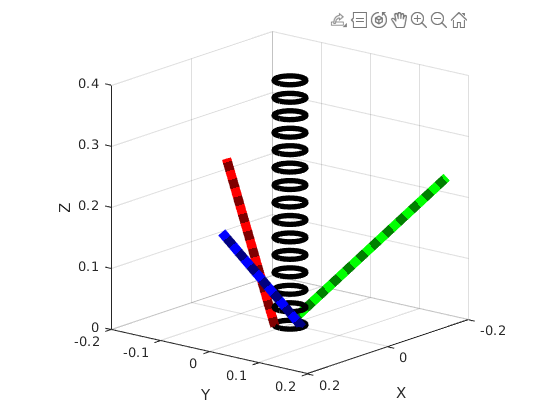

% Initialzie Plotting
muscle_A.color = [1 0 0];
muscle_B.color = [0 1 0];
muscle_C.color = [0 0 1];

% Test plotting
% TODO: Wrap this into its own function?
fig = figure();
ax = axes(fig);

% TODO: Add the color as a property of the muscle object.
line_options_muscles = struct('LineWidth', 7);
line_options_rings = struct('LineWidth', 4);

for i = 1 : length(muscles)
    muscles(i).plot_muscle(ax, 'line_options', line_options_muscles);
end

h_o_tilde_0 = [muscle_A.l; 0; 0; 0; 0; 0];

n_circles = 15;
t_circles = linspace(0, 1, n_circles);
v_lh_circles = matlab.graphics.primitive.Line.empty(0, n_circles);
for i = 1 : n_circles
    v_lh_circles(i) = line(0, 0, 0, 'color', 'k', line_options_rings);
    plot_circle(v_lh_circles(i), rho, g_o * expm_se3(h_o_tilde_0 * t_circles(i)) * inv(g_o));
end

axis equal
border_length_cm = 20;
xlim(ax, [-1, 1] * border_length_cm/100);
ylim(ax, [-1, 1] * border_length_cm/100);
xlabel("X")
ylabel("Y")
zlabel("Z")

view([129.400 16.000])
grid on
% Construct unstrained muscles
if exist('muscles_unstrained', 'var')
    delete(muscles_unstrained)
end

muscles_unstrained = copy(muscles);
for i = 1 : length(muscles) 
    % "Unstrained" line handles: Copy of actual line handles, but darker
    % Displays muscles if they had the same curvature but the actual
    % intended and unstrained length
    hsv_gains = diag([1, 1, 0.5]);
    muscles_unstrained(i).lh.Color = hsv2rgb(rgb2hsv(muscles(i).lh.Color) * hsv_gains);
    muscles_unstrained(i).lh.LineStyle = ':';
end
set(fig, 'visible', true)

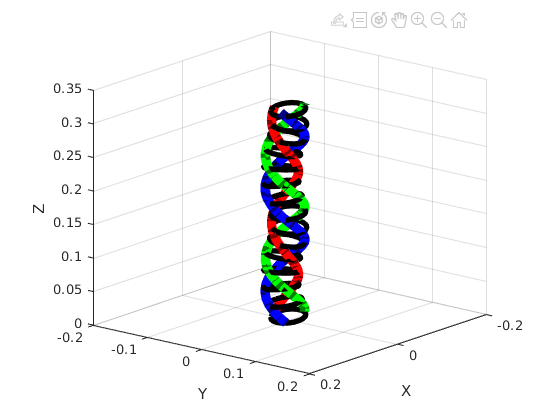

l_A = 0.375; % Red
l_B = 0.48; % Green
l_C = 0.485;  % Blue

plot_base_curve = false;

v_l = [l_A; l_B; l_C];

% Calculate base curve curvature
h_o_tilde = mat_N * v_l;
%h_o_tilde = h_o_tilde_old;

muscle_o.h_tilde = h_o_tilde;

%% Rotate so that the winding axis is vertical
v = h_o_tilde(1:3);
omega = h_o_tilde(4:6);

%Calculate vectors in the base-curve frame
winding_axis_o = omega / norm(omega) * sign(omega(1)); % Normalized winding axis vector
o_o = cross(omega, v) / norm(omega)^2; % Vector from the start of base-curve to the center of the helix

% Calculate vectors in the world frame
winding_axis = g_o(1:3, 1:3) * winding_axis_o;
o = g_o(1:3, 1:3) * o_o;

R_axis = [winding_axis -o/norm(o) cross(winding_axis, -o/norm(o))]; % Rotation matrix for the winding axis

g_offset = g_o * SE3(R_axis', o);

% Plot transform frames
if exist('gh_tf_o', 'var')
    delete(gh_tf_o)
end

if plot_base_curve
    gh_tf_o = muscle_o.plot_tforms(ax, 'g_offset', g_offset, 'plot_options', struct('FrameSize', rho));
end

% Calculate and plot individual muscle lengths
for i = 1 : length(muscles)
    % Rotate the muscles
    muscles(i).g_0 = muscles(i).g_0;
    
    muscles(i).h_tilde = muscles(i).adjoint_X_o * h_o_tilde;
    
    muscles_unstrained(i).h_tilde = muscles(i).h_tilde;
    muscles_unstrained(i).l = v_l(i);
    
    muscles(i).plot_muscle(ax, muscles(i).lh, 'resolution', 40, 'g_offset', g_offset);
    muscles_unstrained(i).plot_muscle(ax, muscles_unstrained(i).lh, 'resolution', 40, 'g_offset', g_offset);
end
for i = 1 : length(v_lh_circles)
    plot_circle(v_lh_circles(i), rho, g_offset * g_o * expm_se3(h_o_tilde * t_circles(i))*inv(g_o));
end

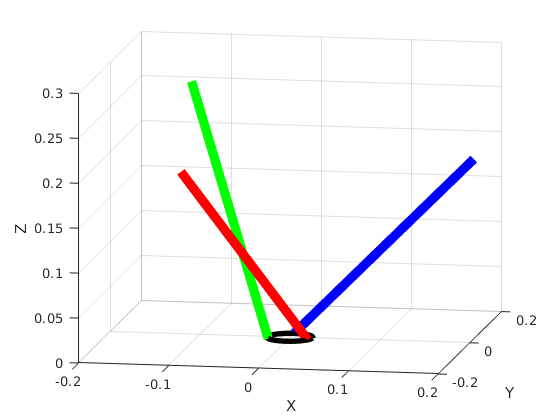

helical_arm_obj = Arm3D(g_o, {g_A, g_B, g_C}, l_0);
helical_arm_obj.rho = rho;

fig = figure();
ax = axes(fig);
helical_arm_obj.initialize_plotting(ax, ...
    "line_options_circles", line_options_rings, ...
    "line_options_muscles", line_options_muscles);

border_length_cm = 20;
xlim(ax, [-1, 1] * border_length_cm/100);
ylim(ax, [-1, 1] * border_length_cm/100);

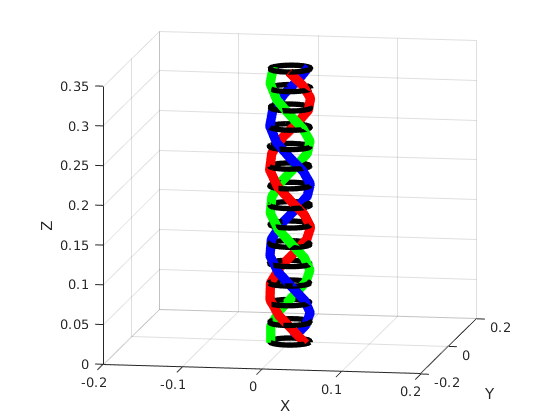

l_A = 0.49; % Red
l_B = 0.48; % Green
l_C = 0.485;  % Blue

v_l = [l_A; l_B; l_C];
helical_arm_obj.update_arm(v_l);